# **EJERCICIOS TEMA 6**

#### **TEMA 6**

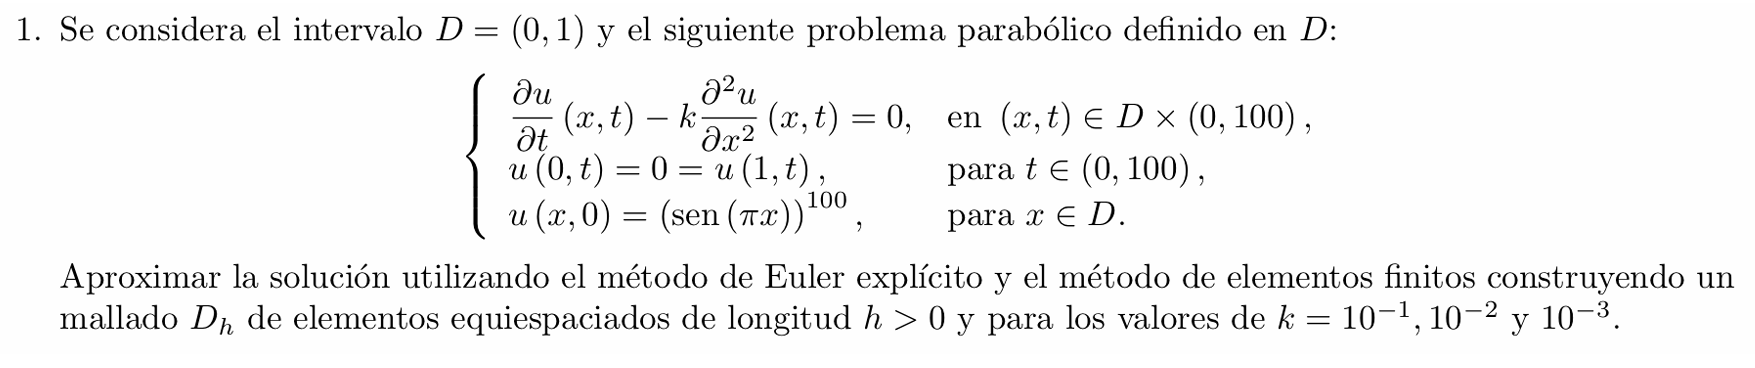

%% EJERCICIO 1 : EULER EXPLÍCITO


En el esquema del euler explícito tenemos que tener en cuenta la estabilidad

`REGÓN ESTABILIDAD: dt<h^2/2kpi`

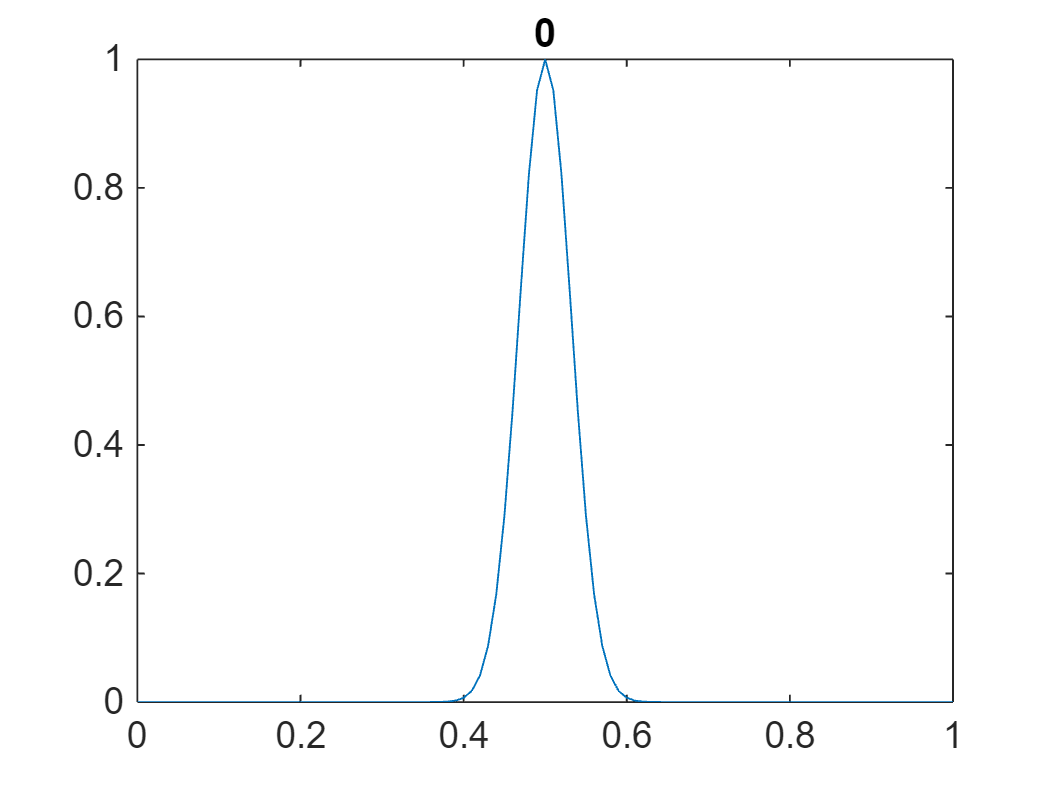

clear all

a= 0;
k=0.1;

% intervalo espacio:
c = 0;
d = 1;

Ne = 100;           % número elementos
h = (d-c)/Ne;
xi = c:h:d;         % nodos

% intervalo tiempo:
t0= 0;
tf= 100;
dt= 0.00016;                
Nt= (tf-t0)/dt;

% Matrices de masas y rigidez las cuales no varían
Calcular_Matriz_Masa_Rigidez_Lineal1D

A = M;
A0 = A;
A0([1 end],:) = 0;
A0(:,[1 end]) = 0;
A0(1,1) = 1;
A0(end,end) = 1;

uhn = sin(pi*xi').^100;
plot(xi,uhn)
title(0)

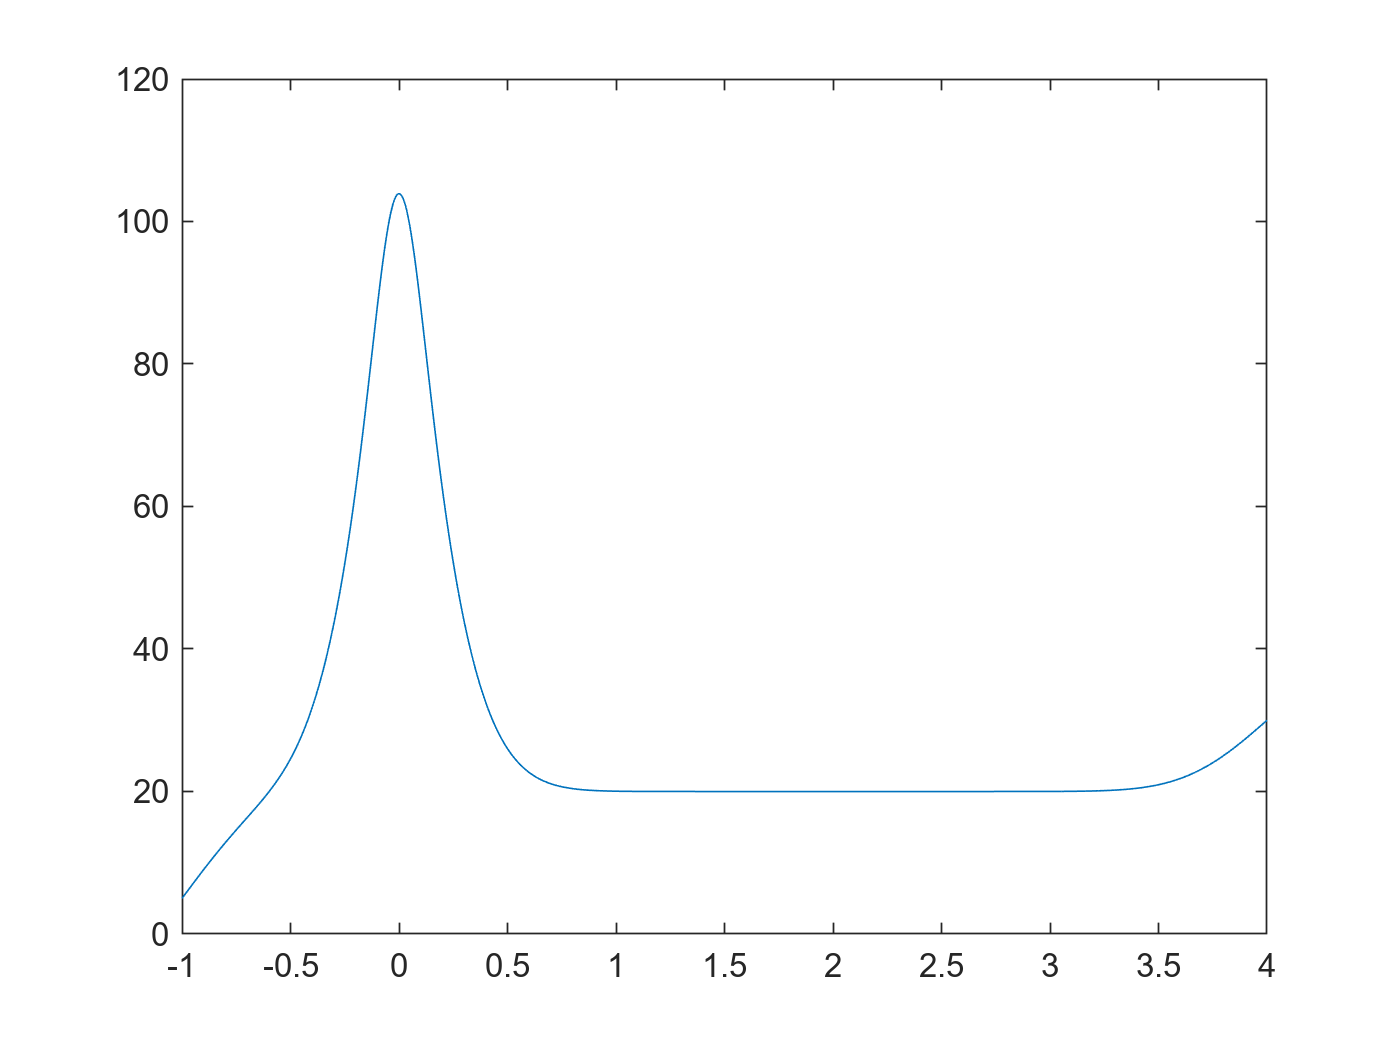

pause(0.0005)

% resolver el pvi con euler explícito 
for n = 1:Nt
    vect_b = ((1-a*dt)*M-k*dt*R)*uhn;
    vect_b0 = vect_b;
    vect_b0([1 end])=0;

    uhn = A0\vect_b0; 

    plot(xi,uhn)
    title(n*dt)
    axis([0 1 -.2 1.2])

    pause(0.00005)
end

Es incondicionalmente estable 

clear all

a= 0;
k=0.1;

% intervalo espacio:
c = 0;
d = 1;

Ne = 100;           % número elementos
h = (d-c)/Ne;
xi = c:h:d;         % nodos

% intervalo tiempo:
t0= 0;
tf= 100;
dt= 0.016;                
Nt= (tf-t0)/dt;

% Matrices de masas y rigidez las cuales no varían
Calcular_Matriz_Masa_Rigidez_Lineal1D

A = M + k*dt*R;
A0 = A;
A0([1 end],:) = 0;
A0(:,[1 end]) = 0;
A0(1,1) = 1;
A0(end,end) = 1;

uhn = sin(pi*xi').^100;
plot(xi,uhn)
title(0)

pause(0.0005)

% resolver el pvi con euler explícito 
for n = 1:Nt
    vect_b = M*uhn;
    vect_b0 = vect_b;
    vect_b0([1 end])=0;

    uhn = A0\vect_b0; 

    plot(xi,uhn)
    title(n*dt)
    axis([0 1 -.2 1.2])

    pause(0.00005)
end

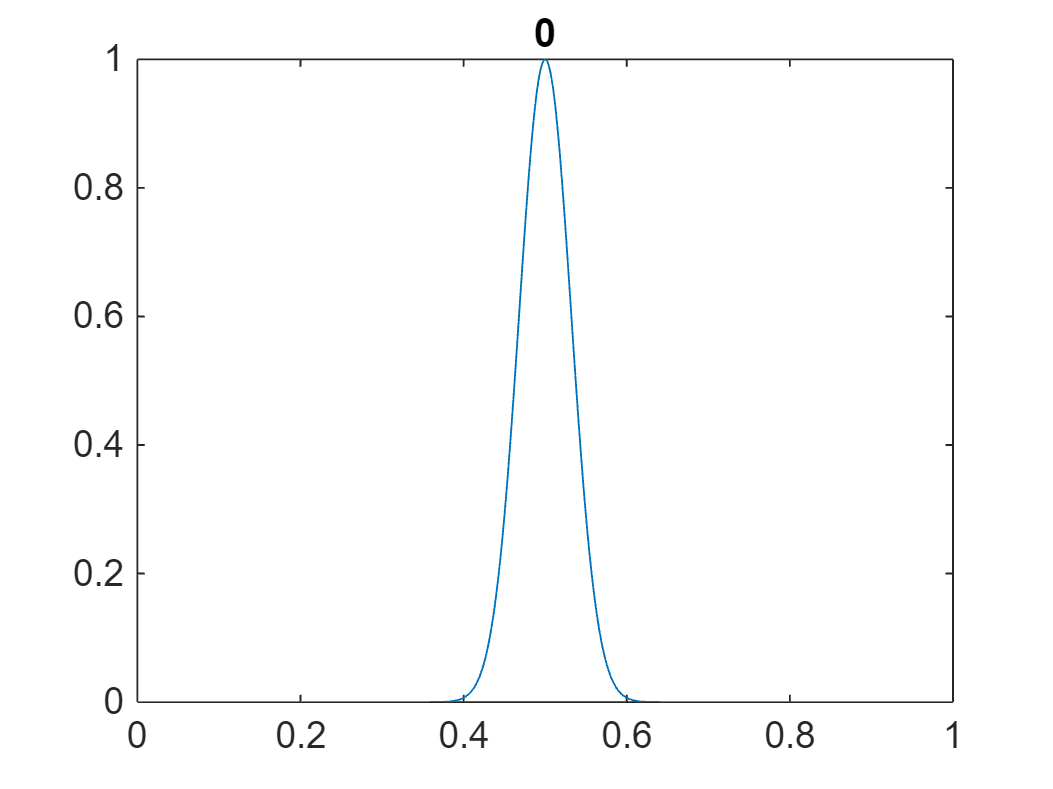

clear all

a= 0;
k=0.1;

% intervalo espacio:
c = 0;
d = 1;

Ne = 1000;           % número elementos
h = (d-c)/Ne;
xi = c:h:d;         % nodos

% intervalo tiempo:
t0= 0;
tf= 100;
dt= 0.01;                % incondicionalmente estable
Nt= (tf-t0)/dt;

% Matrices de masas y rigidez las cuales no varían
Calcular_Matriz_Masa_Rigidez_Lineal1D

A = (M + 0.5*R*k*dt);
A0 = A;
A0([1 end],:) = 0;
A0(:,[1 end]) = 0;
A0(1,1) = 1;
A0(end,end) = 1;

uhn = sin(pi*xi').^100;
plot(xi,uhn)
title(0)

pause(3)

% resolver el pvi con euler implícito 
for n = 1:Nt
    vect_b = (M - 0.5*dt*k*R)*uhn;
    vect_b0 = vect_b;
    vect_b0([1 end])=0;

    uhn = A0\vect_b0; 

    plot(xi,uhn)
    title(n*dt)
    axis([0 1 -.2 1.2])

    pause(0.0005)
    %Ctrol+C para parar la grafica
end

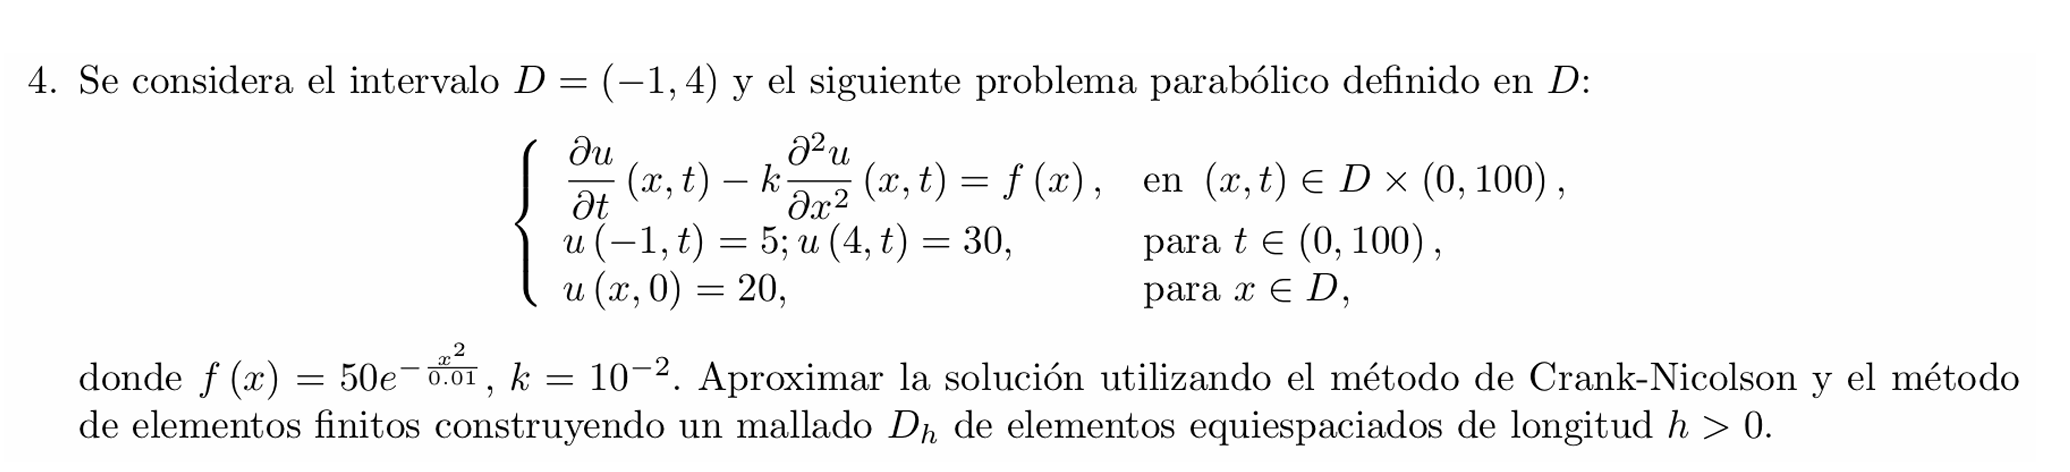

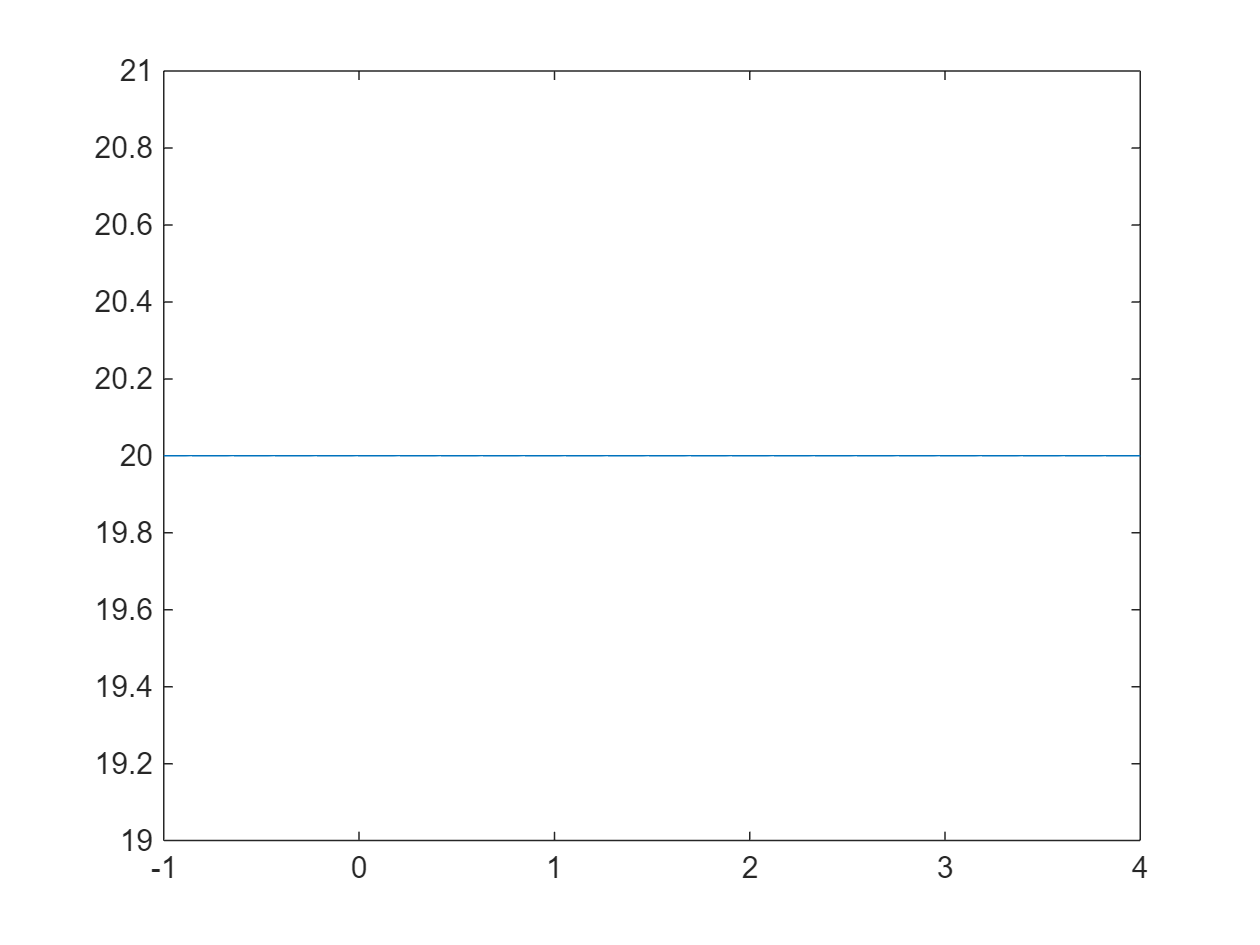

%% EJERCIIO 4 : edp parabólica con trapecios y condiciones no homo

clear;

% Definir la función 
f = @(x) 50 * exp(-x.^2 / 0.01);
a = 0; 
k = 0.01;

% Intervalo espacio
c = -1; 
d = 4;
Ne = 1000;               % Número de elementos
h = (d - c) / Ne;        % Tamaño del paso 
xi = c:h:d;              % Nodos del mallado 


% Intervalo tiempo
t0 = 0; 
tf = 100;
dt = 0.016;           
Nt = (tf - t0) / dt;    

% Matrices de masas y rigidez las cuales no varían
Calcular_Matriz_Masa_Rigidez_Lineal1D

A = M + 0.5*dt*k*R;
A0 = A;
A0([1, end], :) = 0;     
A0(:, [1, end]) = 0;    
A0(1, 1) = 1;           
A0(end, end) = 1;       

% función g para condiciones de contorno homogéneas
gi = 0 * xi'; 
gi(1) = 5;               
gi(end) = 30;      

% Condición inicial y funcion evaluada en los nodos
uhn = 0 * xi' + 20;
whn = uhn;
fi = f(xi)';

plot(xi', uhn);

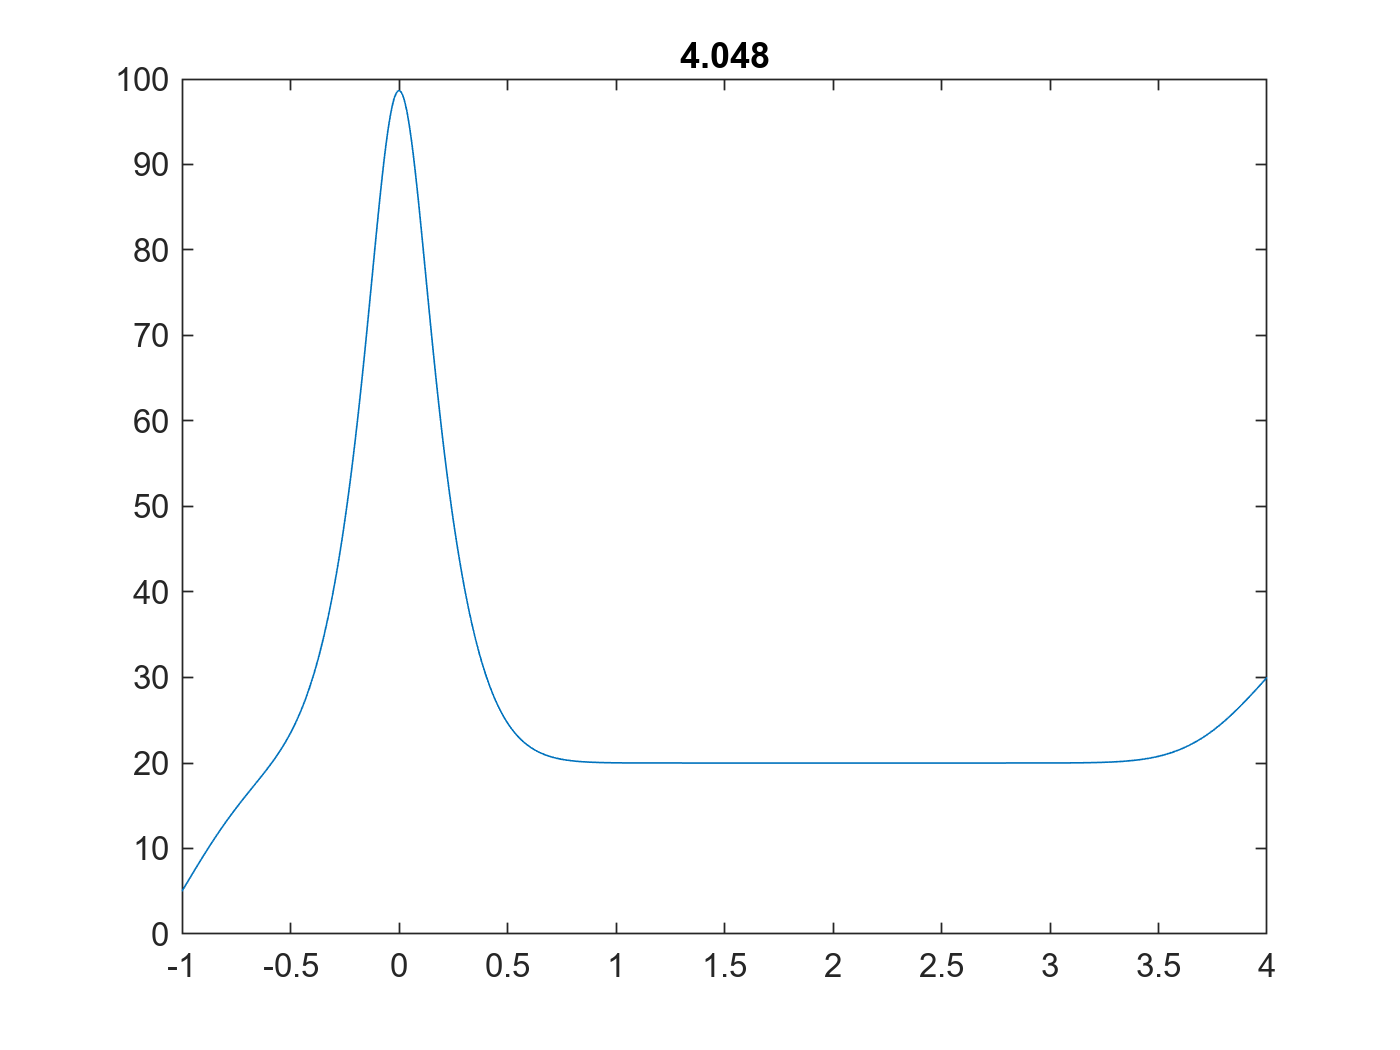

%pause(0.5);

% resolver problemas elípticos
for n = 1:Nt

    vect_b = (M - 0.5*k*dt*R)*uhn + dt*M*(fi) - A*gi;
    vect_b0 = vect_b;
    vect_b0(1) = 0;          
    vect_b0(end) = 0;       

    % Resolver el sistema lineal
    whn = A0 \ vect_b0;
    uhn = whn + gi;
    
    plot(xi,uhn)
    title(n*dt)

     pause(0.005)
end

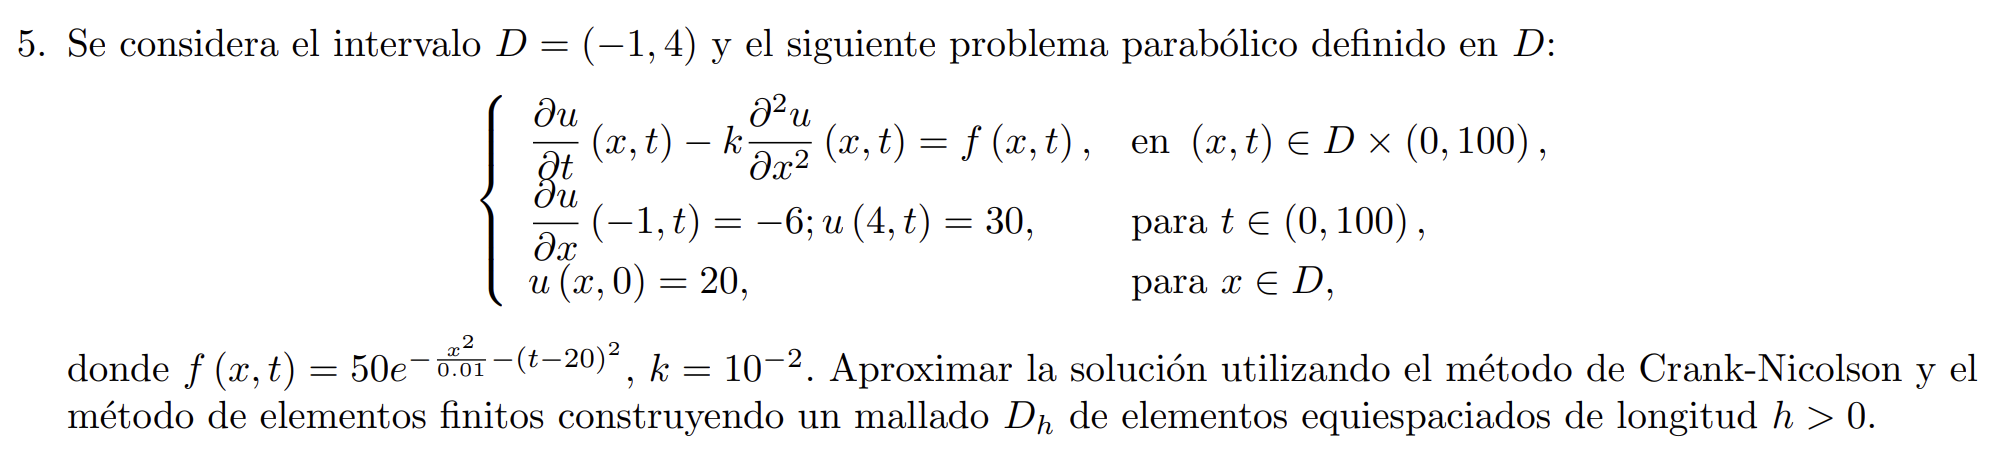

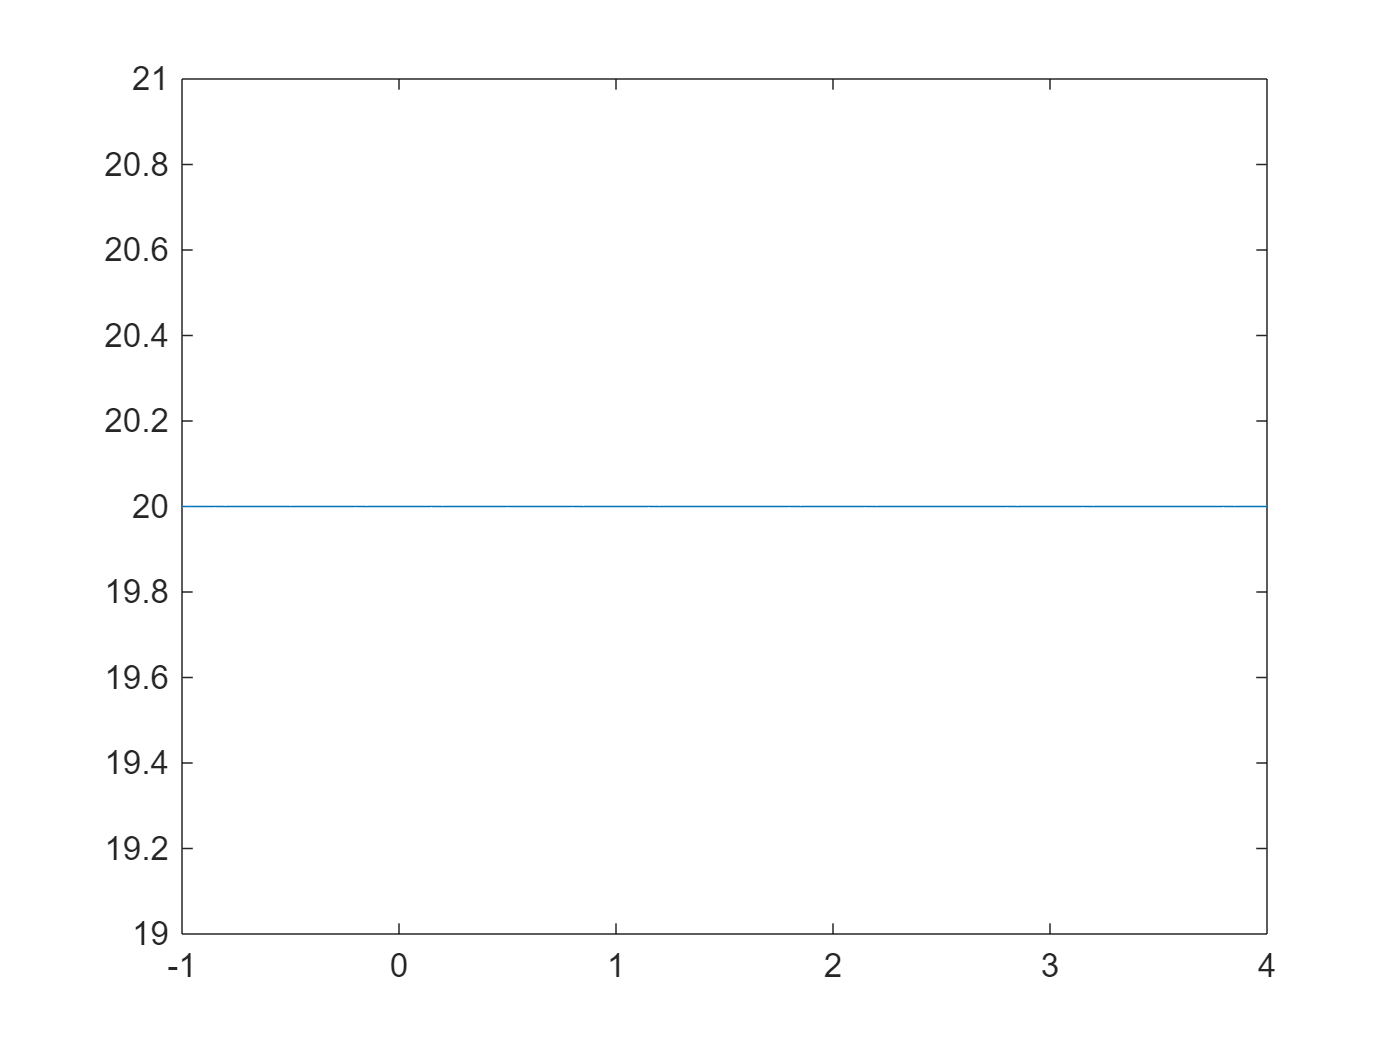


clear;

% Definir la función 
f = @(x,t) 50 * exp((-x.^2 / 0.01) - (t-20.^2)) ;
 a = 0; 
k = 0.01;

% Intervalo espacio
c = -1; 
d = 4;
Ne = 100;               % Número de elementos
h = (d - c) / Ne;        % Tamaño del paso 
xi = c:h:d;              % Nodos del mallado 


% Intervalo tiempo
t0 = 0; 
tf = 100;
dt = 0.016;           
Nt = (tf - t0) / dt;    

% Matrices de masas y rigidez las cuales no varían
Calcular_Matriz_Masa_Rigidez_Lineal1D

A = M + 0.5*dt*k*R;
A0 = A;
A0([1, end], :) = 0;     
A0(:, [1, end]) = 0;    
A0(1, 1) = 1;           
A0(end, end) = 1;       

% función g para condiciones de contorno homogéneas
gi = 0 * xi'; 
gi(1) = 5;               
gi(end) = 30;      

% Condición inicial y funcion evaluada en los nodos
uhn = 0 * xi' + 20;
whn = uhn;
fi0 = f(xi',t0);
fi1 = f(xi', t0 +dt);
plot(xi', uhn);

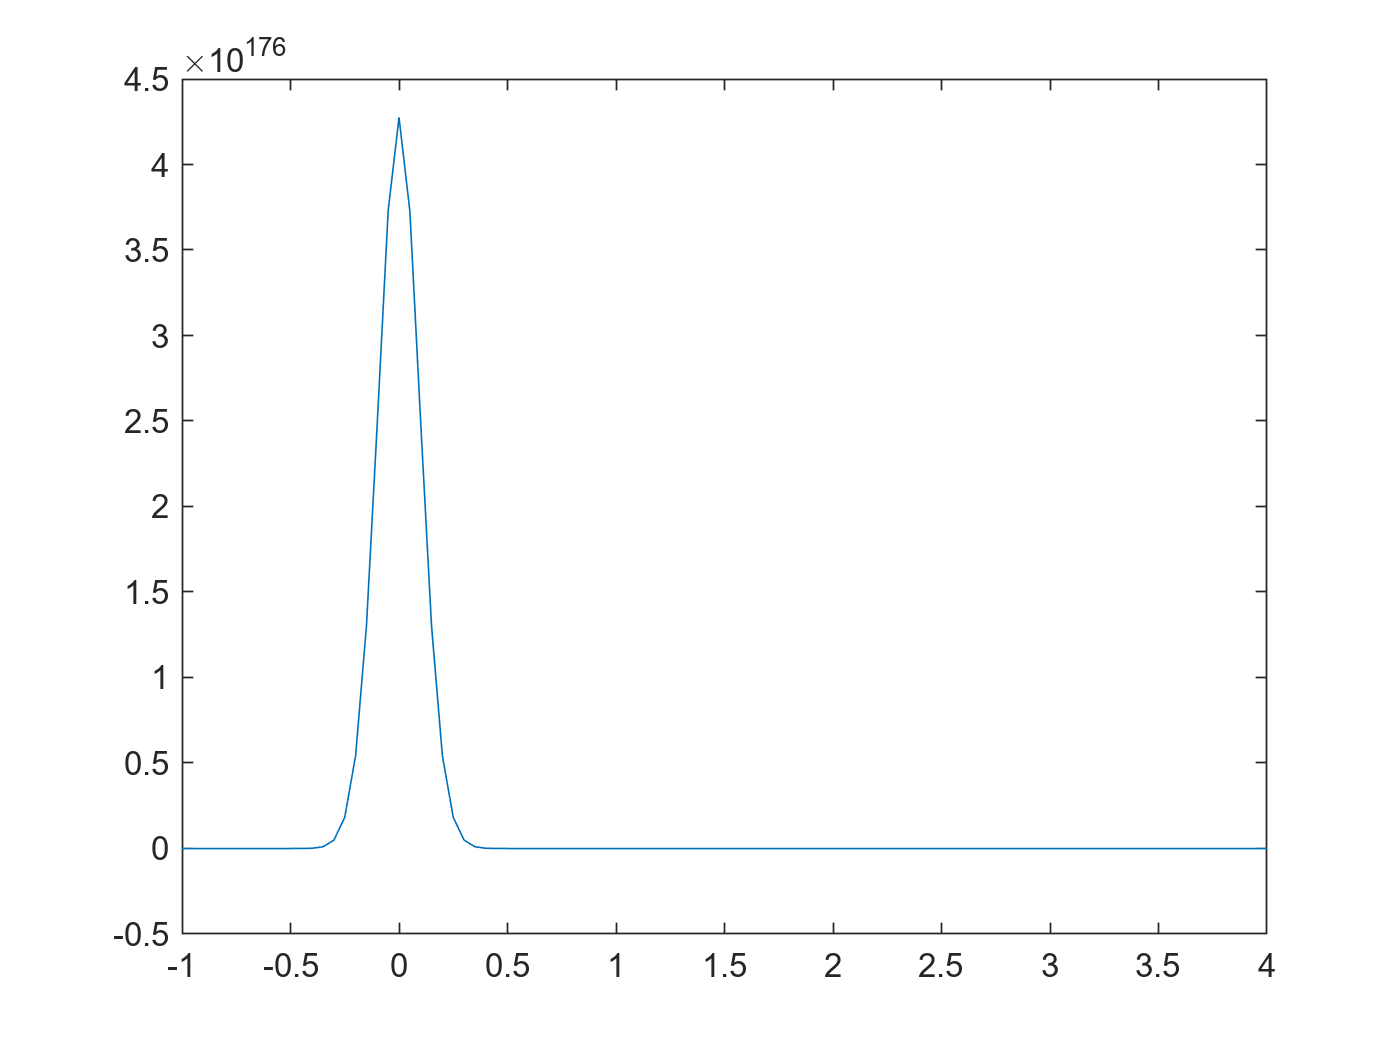

%pause(0.5);

% resolver problemas elípticos
for n = 1:Nt

    vect_b = (M - 0.5*k*dt*R)*uhn + dt+0.5*M*(fi0+fi1) - A*gi;
    vect_b0 = vect_b;
    vect_b0(1) = - 6*k*dt;          
    vect_b0(end) = 0;       

    % Resolver el sistema lineal
    whn = A0 \ vect_b0;
    uhn = whn + gi;

    fi0= f(xi', n*dt);
    fi1= f(xi', n*dt + dt);

    
    plot(xi,uhn)
    title(n*dt)

     pause(0.0005)
end

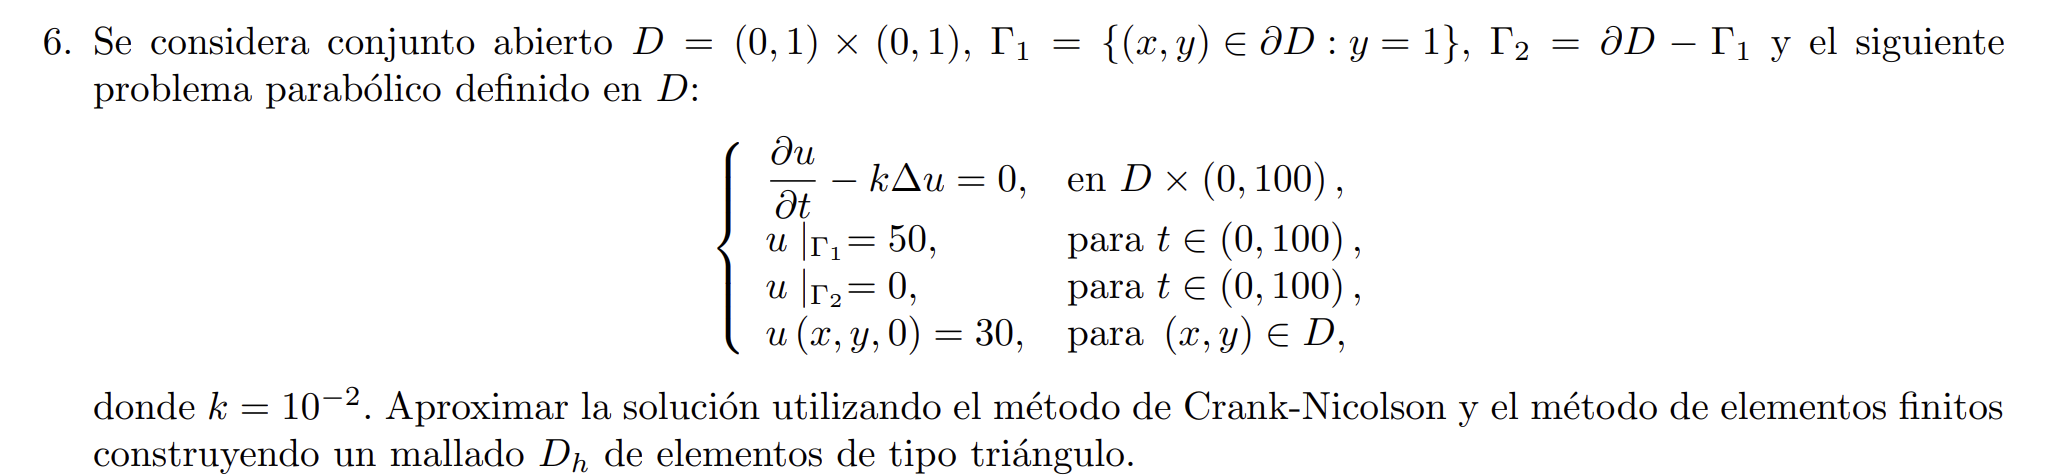

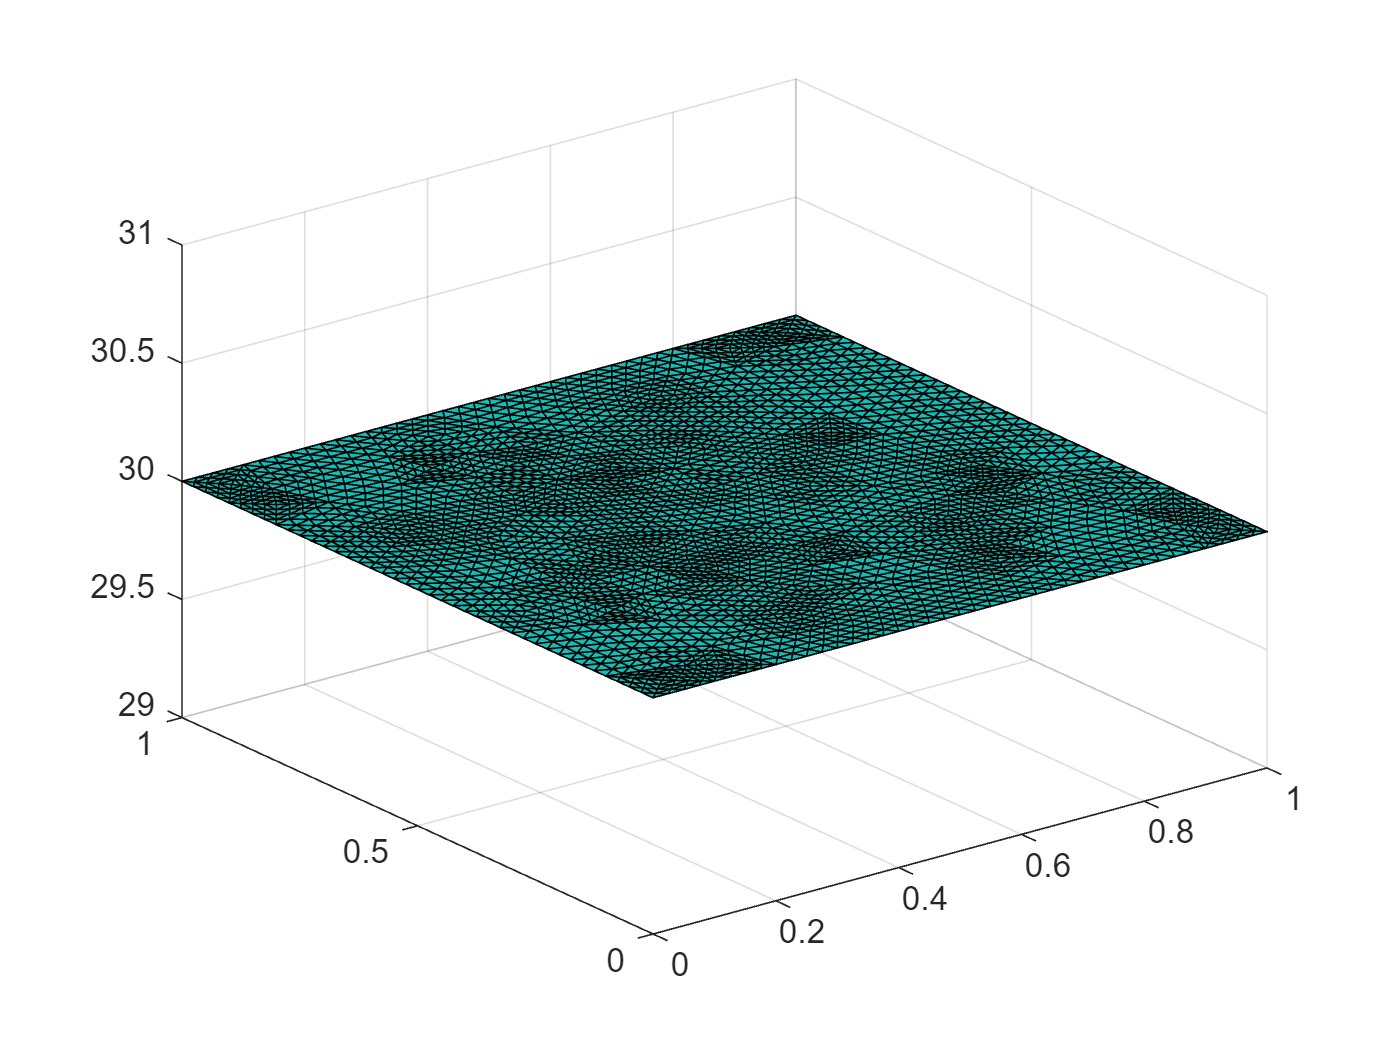

clear;

% Definir la función 
f = @(x,y) 0.*x + 0.*y;
a = 0; 
k = 0.01;

    % MALLADO
load("malla_ej6.mat")
xi = p(1,:);
yi = p(2,:);
elem = t(1:3,:)';

fron_d = unique([e(1,:) e(2,:)]); %no repetidos
ind_1 = find(yi==1);

% Intervalo tiempo
t0 = 0; 
tf = 100;
dt = 0.2;           
Nt = (tf - t0) / dt;    

% Matrices de masas y rigidez las cuales no varían
[R M] = assema(p,t,1,1,0);

A = M + 0.5*dt*k*R;
A0 = A;
A0(fron_d, :) = 0;     
A0(:, fron_d) = 0;    
for i = fron_d
    A0(i,i) = 1;
end
      

% función g para condiciones de contorno homogéneas
gi = 0 * xi'; 
gi(ind_1) = 50;               

% Condición inicial y funcion evaluada en los nodos
uhn = 0 * xi' + 0*yi' + 30;
whn = uhn;
fi = f(xi,yi)';

trisurf(elem,xi, yi, uhn);

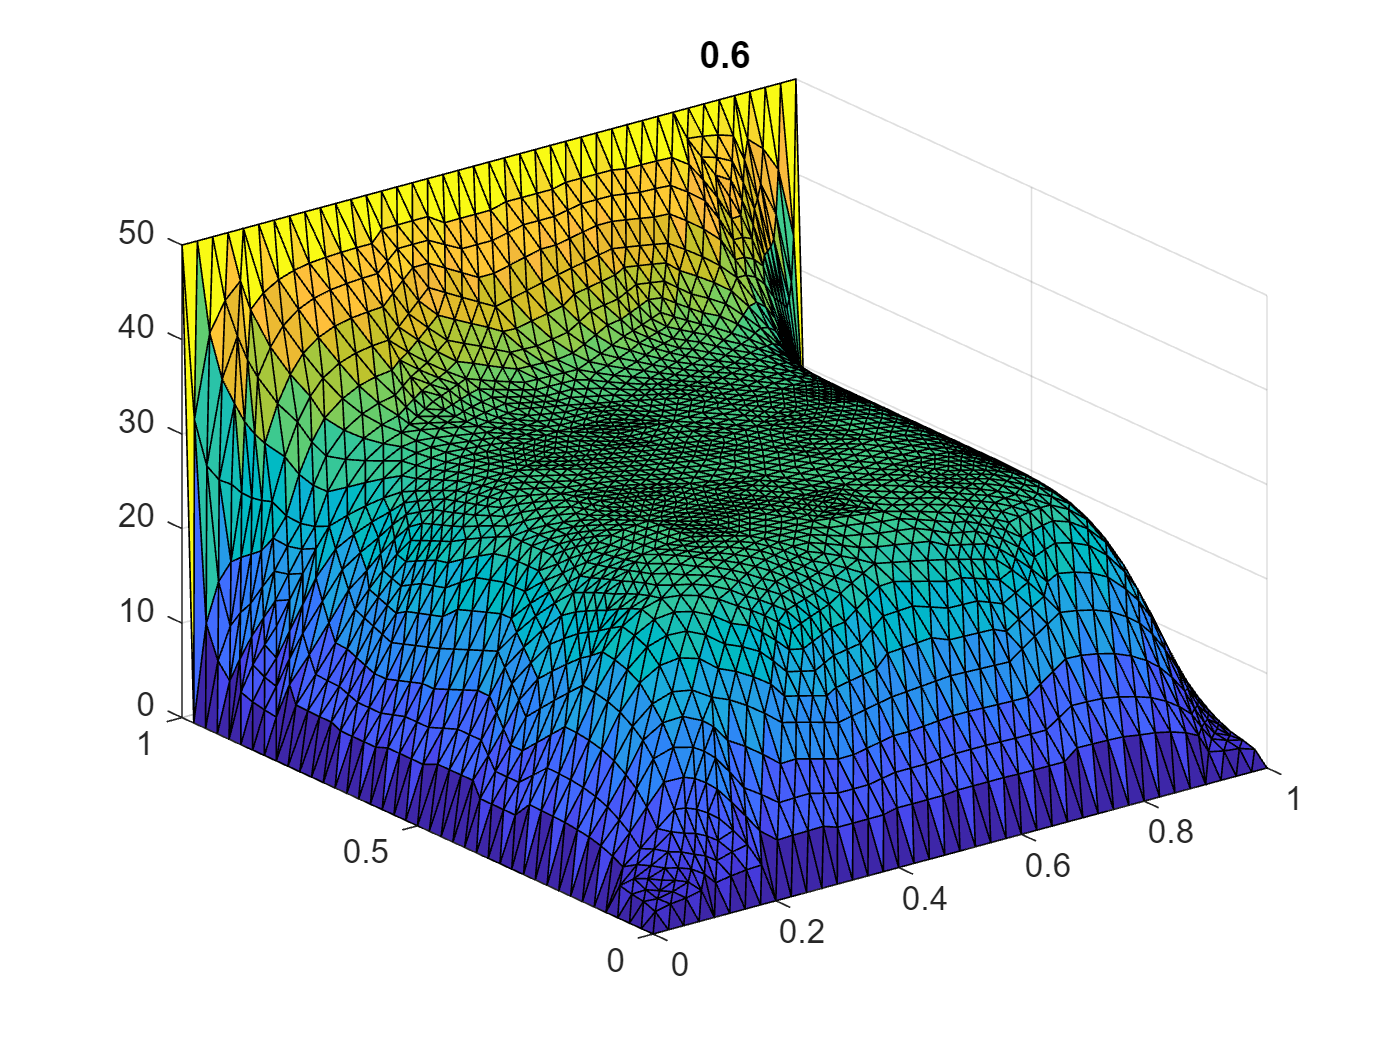

pause;

% resolver problemas elípticos
for n = 1:Nt

    vect_b = (M - 0.5*k*dt*R)*uhn + dt*M*(fi) - A*gi;
    vect_b0 = vect_b;
    vect_b0(fron_d) = 0;          

    % Resolver el sistema lineal
    whn = A0 \ vect_b0;
    uhn = whn + gi;
    
trisurf(elem,xi,yi,uhn)
    title(n*dt)

     pause
end